clc,clear
s=tf('s');

This is your system's open loop transfer function. Replace as per your system design.


$$G\left(s\right)=\frac{1}{\left(2s+1\right)}$$


G= 1/(2*s+1);

Design the K to sarisfy the stready state error requirements and add integrator to ensure zero steady state error. Reduce the gain if compensator is not able to acheive the desired phase margin. In some case a compensator may not be sufficient to achive the desired phase margin, in that case both lead and lag compensator will be required.

K=100;
G=K*G*(1/s);

Find system margins without compensator,

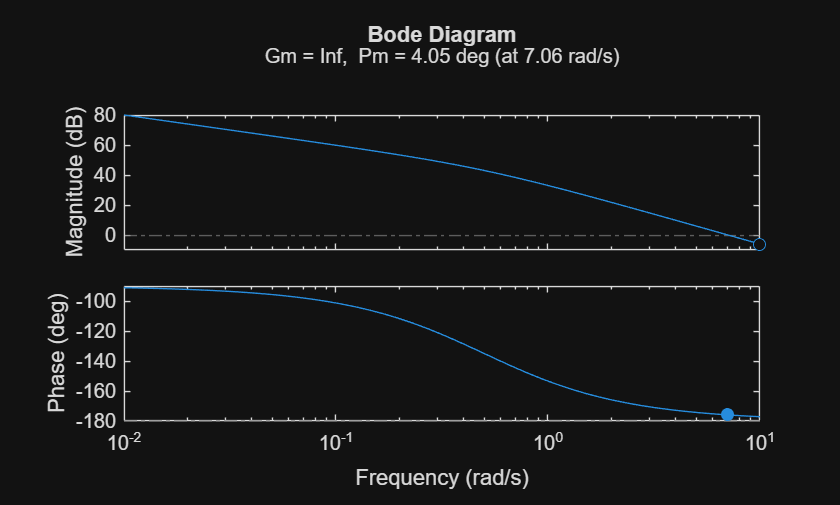

margin(G)

% Display the gain and phase margins
[Gm, Pm, Wcg, Wcp] = margin(G);
fprintf('Gain Margin: %.2f dB at Frequency: %.2f rad/s\n', db(Gm), Wcg);

Gain Margin: Inf dB at Frequency: Inf rad/s


fprintf('Phase Margin: %.2f degrees at Frequency: %.2f rad/s\n', Pm, Wcp);

Phase Margin: 4.05 degrees at Frequency: 7.06 rad/s


i=1;
for phi_d = [30,40,45,50,60]
    phi_di(i,:)=phi_d;
    phi_m(i,:)=phi_d-Pm+5;
    alpha(i,:) = (1-sind(phi_m(i,:)))/(1+sind(phi_m(i,:)));

Automatic $\omega_d$calculation

    alpha_attenuation = 10*log10(alpha(i,:));
    [mag,phase,wout] = bode (G);
    mag_db=mag2db(mag);
    [~,index] = min(abs(mag_db-alpha_attenuation));
    omega = wout(index);

Claculate the compensator time constat to place the additional phase at $\omega_{d\;}$frequency.


$$\tau =\frac{1}{\omega_{d\;\sqrt{\alpha }} }$$


    tau(i,:) = 1/(omega*sqrt(alpha(i,:)));
    
    C= (1+tau(i,:)*s)/(1+alpha(i,:)*tau(i,:)*s);
    figure(1)
    margin(G*C)
    hold on

The frequency response of the Designed Compensator

    figure(2)
    bode(C)
    hold on
    [gm(i,:),pm(i,:)] = margin(G*C);
    fprintf("Gain Margin = %0.2f, and Phase Margin = %0.2f \n",[db(gm(i,:)),pm(i,:)])

Step response of uncompensated closed loop system and compensated closed loop system with the desired phase margins.

    figure(3)
    step(feedback(G*C,1),3)
    hold on
    i=i+1;
end

Gain Margin = Inf, and Phase Margin = 34.00 
Gain Margin = Inf, and Phase Margin = 43.56 
Gain Margin = Inf, and Phase Margin = 47.99 
Gain Margin = Inf, and Phase Margin = 52.04 
Gain Margin = Inf, and Phase Margin = 58.64 


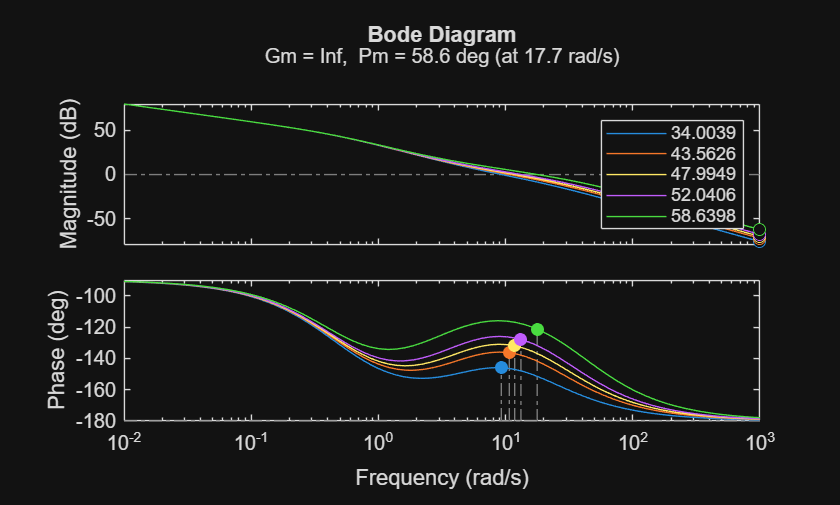

step(feedback(G,1),3)
figure(1),legend(pm);

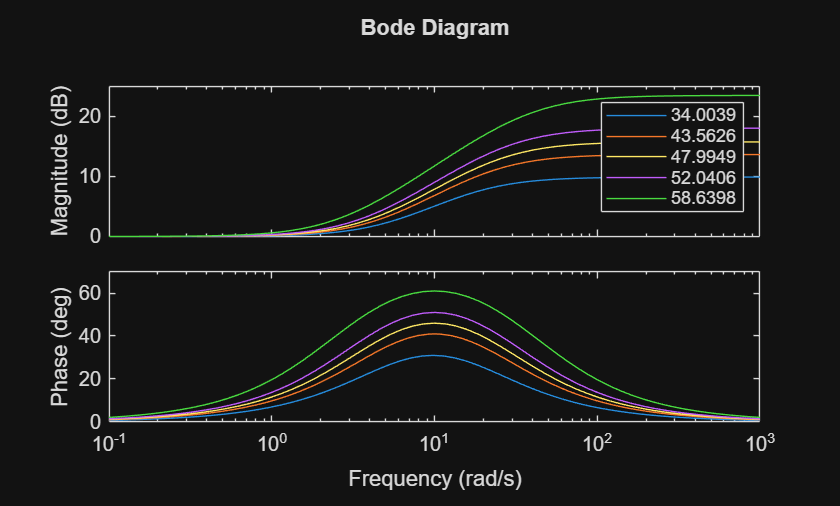

figure(2),legend(pm);

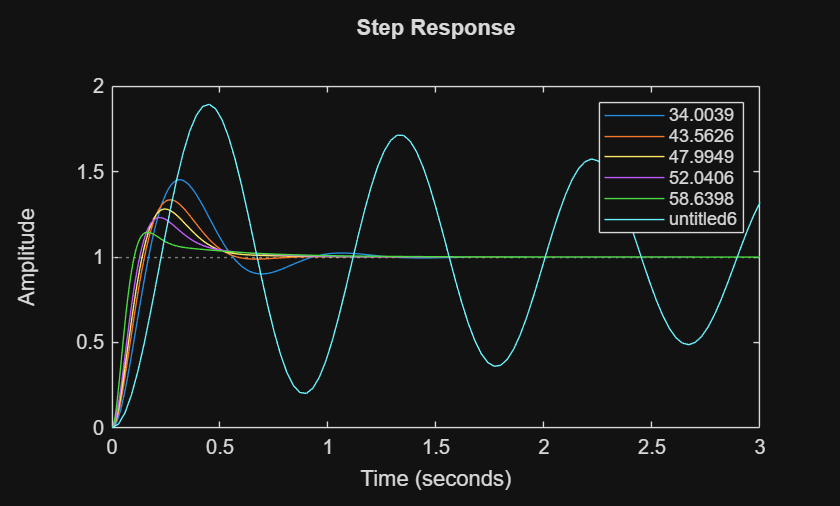

figure(3),legend(pm);
hold off

PM_uncomensated = ones(size(phi_di))*Pm;
tab=table(phi_di,PM_uncomensated,pm,alpha,tau, ...
    'VariableNames',["PM (Desired)","PM (Actual)", 'PM (Compensated)', "alpha","tau"])

tab = 5×5 table
    PM (Desired)    PM (Actual)    PM (Compensated)     alpha        tau  
    ____________    ___________    ________________    ________    _______

         30           4.0498            34.004          0.32075    0.18061
         40           4.0498            43.563          0.20817    0.21918
         45           4.0498            47.995          0.16365     0.2472
         50           4.0498            52.041          0.12575      0.282
         60           4.0498             58.64         0.067123    0.38598


Pm

Pm = 4.0498